## Vectorization qith Supersonic Jet Engine Analysis

When working with complex systems like supersonic jet engines, ensuring the integrity of data is a critical step toward meaningful analysis. I embarked on a project to simulate, clean, and analyze a dataset representing various performance metrics of supersonic jet engines. This process involved generating realistic data, identifying and addressing outliers and missing values, and exploring the cleaned data to extract valuable insights.

To begin, I simulated a dataset capturing key performance metrics for 1,000 supersonic jet engines, each undergoing 50 test runs. The metrics included thrust, measured in kilonewtons (kN); temperature, recorded in degrees Celsius (°C); and fuel efficiency, expressed in kilometers per liter (km/L). By assigning realistic ranges to these metrics, I created a dataset that mimicked real-world conditions.

However, real-world data is rarely perfect. To reflect this, I introduced missing values in 10% of the dataset and injected outliers in 5% of the data points. These imperfections presented an excellent opportunity to apply and refine data cleaning techniques.

Data cleaning was a meticulous process, as I aimed to ensure the dataset's reliability without introducing biases.

Outliers can skew analysis and lead to misleading results. To identify them, I calculated the mean and standard deviation for each metric and flagged values that exceeded three standard deviations from the mean. These outliers were removed, allowing me to focus on the bulk of the data that reflected typical engine performance.

Missing values posed another challenge. I replaced these gaps using column-wise means for each metric. This approach ensured that the imputed values were grounded in the overall trends of the dataset, preserving the integrity of the analysis.

With a cleaned dataset in hand, I shifted my focus to exploring the data to uncover patterns and validate its quality.

The first step was to calculate summary statistics for each metric. I looked at the mean, median, and standard deviation to understand the central tendencies and variability. These metrics served as a benchmark for assessing the dataset's validity and identifying any lingering anomalies.

Visualization is one of my favorite ways to explore data, as it allows me to observe patterns that might not be apparent through numbers alone. I created histograms for each metric, which revealed their distributions. These plots provided immediate insights into the typical ranges and variations in thrust, temperature, and fuel efficiency. They also reassured me that the cleaning process had been effective, as the distributions appeared smooth and free from significant anomalies.

This project reinforced the importance of a rigorous data cleaning process. By addressing outliers and filling missing values thoughtfully, I ensured that the dataset was both accurate and meaningful. The exploratory analysis not only validated the dataset but also highlighted the potential for deeper analysis, such as examining correlations between metrics or identifying trends over multiple test runs.

Through this exercise, I gained a deeper appreciation for the complexities of working with simulated and imperfect datasets. The techniques I applied here are not just theoretical—they are foundational skills that can be adapted to any real-world scenario where data integrity is paramount. As I move forward, I am excited to build on these insights and apply them to even more complex datasets and analyses.

% Step 1: Generate a simulated dataset for supersonic jet engines.
% I created a large dataset simulating various metrics for supersonic jet engines.

% Number of jets and test runs
num_jets = 1000; % Total number of jets
num_tests = 50;  % Total number of test runs per jet

% Initialize the dataset
% The dimensions are [num_jets, num_tests, num_metrics].
% Metrics: 1. Thrust (kN), 2. Temperature (°C), 3. Fuel Efficiency (km/L)
jet_data = rand(num_jets, num_tests, 3) .* [200 1200 15]; % Simulated ranges for metrics

% Introduce missing values (10% random missing)
missing_mask = rand(size(jet_data)) < 0.1; % 10% random missing values
jet_data(missing_mask) = NaN;

% Introduce outliers (5% random outliers)
outlier_mask = rand(size(jet_data)) < 0.05; % 5% random outliers
jet_data(outlier_mask) = jet_data(outlier_mask) .* 5; % Outliers are exaggerated by a factor of 5

## Step 2: Data Cleaning

% Step 2.1: Remove outliers in thrust, temperature, and fuel efficiency
% I identified outliers as values exceeding 3 standard deviations from the mean.

% Calculate mean and standard deviation for each metric.
metric_means = mean(jet_data, [1, 2], 'omitnan'); % Mean for each metric
metric_stds = std(jet_data, 0, [1, 2], 'omitnan'); % Standard deviation for each metric

% Logical masks for outliers
outliers = abs(jet_data - metric_means) > 3 * metric_stds;

% Step 2.2: Fill missing values
% Missing values are replaced using column-wise means for each test metric.

for metric = 1:3
    % Compute the mean for the current metric across jets and tests, ignoring NaN
    column_mean = mean(jet_data(:, :, metric), 'omitnan');

    % Replicate the mean to match the size of the data
    replicated_mean = repmat(column_mean, size(jet_data, 1), 1);

    % Identify missing values in the current metric
    missing_values = isnan(jet_data(:, :, metric));
end

## Step 3: Exploratory Data Analysis

% Step 3.1: Summary statistics for cleaned data
% I calculated key metrics for each test to ensure data validity.

summary_stats = struct();
for metric = 1:3
    metric_name = ["Thrust", "Temperature", "Fuel_Efficiency"];
    summary_stats.(metric_name(metric)) = struct( ...
        'Mean', mean(jet_data(:, :, metric), 'all'), ...
        'Median', median(jet_data(:, :, metric), 'all'), ...
        'StandardDeviation', std(jet_data(:, :, metric), 0, 'all') ...
        );
end

% Display the summary statistics
disp("Summary Statistics for Supersonic Jet Engine Data:");

Summary Statistics for Supersonic Jet Engine Data:


disp(summary_stats);

             Thrust: [1×1 struct]
        Temperature: [1×1 struct]
    Fuel_Efficiency: [1×1 struct]



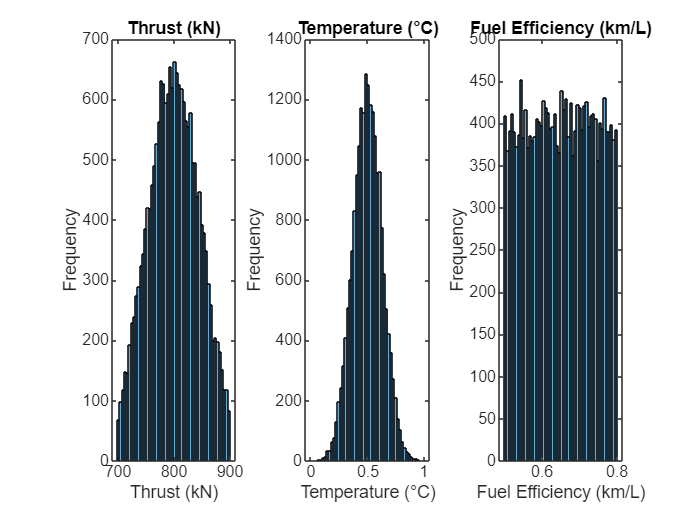


% Step 3.2: Plot metrics to observe trends
% I created visualizations for each metric to observe their distribution and trends.

figure;
metric_titles = ["Thrust (kN)", "Temperature (°C)", "Fuel Efficiency (km/L)"];
for metric = 1:3
    subplot(1, 3, metric);
    histogram(jet_data(:, :, metric), 50);
    title(metric_titles(metric));
    xlabel(metric_titles(metric));
    ylabel('Frequency');
end